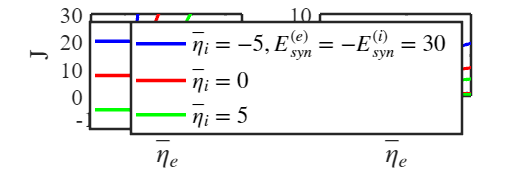

load('COBA2etain5.mat')
load('COBA2etai0.mat')
load('COBA2etai5.mat')

load('CUBA2etain5.mat')
load('CUBA2etai0.mat')
load('CUBA2etai5.mat')

% Crea la figura para el subplot con dimensiones más amplias
figure('Units', 'inches', 'Position', [0, 0, 15, 5]); % 15 pulgadas de ancho, 5 pulgadas de alto

% Primer subplot - CUBA a la izquierda
subplot(1,2,1);
plot(CUBA2Jn5, CUBA2etan5,'-b', 'LineWidth', 2); % Línea azul para eta_i = -5
hold on;
plot(CUBA2J0, CUBA2eta0, '-r', 'LineWidth', 2); % Línea roja para eta_i = 0
plot(CUBA2J5, CUBA2eta5, '-g', 'LineWidth', 2); % Línea verde para eta_i = 5
hold off;
set(gca, 'FontSize', 14); % Cambia el tamaño de fuente de los ejes
ylabel('J', 'FontSize', 16); % Etiqueta del eje Y
xlabel('$\bar{\eta}_e$', 'Interpreter', 'latex', 'FontSize', 16); % Etiqueta del eje X con barra

% Añade una leyenda
legend({'$\bar{\eta}_i = -5$','$\bar{\eta}_i = 0$','$\bar{\eta}_i = 5$'}, 'Interpreter', 'latex', 'FontSize', 14, 'Location', 'northeast');

% Ajuste de los límites de los ejes para dar espacio adicional
xlim([-10 35]);
ylim([0 30]);

% Mejora la presentación
set(gcf, 'Color', 'w'); % Establece el color de fondo de la figura a blanco
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes
set(gca, 'FontName', 'Times New Roman'); % Cambia la fuente de los ejes

% Segundo subplot - COBA a la derecha
subplot(1,2,2);
plot(etae_COBA2etain5,g_COBA2etain5, '-b', 'LineWidth', 2); % Línea azul para eta_i = -5
hold on;
plot(etae_COBA2etai0,g_COBA2etai0, '-r', 'LineWidth', 2); % Línea roja para eta_i = 0
plot(etae_COBA2etai5,g_COBA2etai5, '-g', 'LineWidth', 2); % Línea verde para eta_i = 5
hold off;
set(gca, 'FontSize', 14); % Cambia el tamaño de fuente de los ejes
ylabel('g', 'FontSize', 16); % Etiqueta del eje Y
xlabel('$\bar{\eta}_e$', 'Interpreter', 'latex', 'FontSize', 16); % Etiqueta del eje X con barra

% Añade una leyenda con la información de \(\eta\) y \(E_{syn}\) en la primera entrada
legend({'$\bar{\eta}_i = -5, \, E_{syn}^{(e)} = -E_{syn}^{(i)} = 30$', '$\bar{\eta}_i = 0$', '$\bar{\eta}_i = 5$'}, 'Interpreter', 'latex', 'FontSize', 14, 'Location', 'northeast');


% Ajuste de los límites de los ejes para dar espacio adicional
xlim([0 35]);
ylim([0 10]);

% Mejora la presentación
set(gcf, 'Color', 'w'); % Establece el color de fondo de la figura a blanco
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes
set(gca, 'FontName', 'Times New Roman'); % Cambia la fuente de los ejes

% Guardar la figura en alta definición
set(gcf, 'PaperPositionMode', 'auto');
print('Phase_Diagram', '-dpng', '-r300'); % Guarda la figura como PNG a 300 dpi

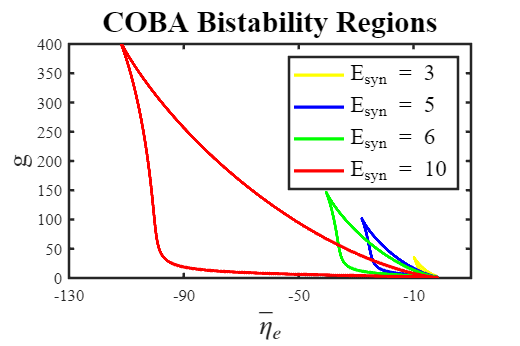

load('Diagram_Bif_COBA_3.mat')
load('Diagram_Bif_COBA_5.mat')
load('Diagram_Bif_COBA_6.mat')
load('Diagram_Bif_COBA_10.mat')

figure('Units', 'inches', 'Position', [0, 0, 6, 4]);
plot(eta_COBA3,g_COBA3, 'LineWidth', 2, 'Color','yellow')
hold on
plot(eta_COBA,g_COBA, 'LineWidth', 2, 'Color','blue')
hold on
plot(eta_COBA6,g_COBA6, 'LineWidth', 2, 'Color','green')
hold on
plot(eta_COBA10,g_COBA10, 'LineWidth', 2, 'Color','red')
hold off
xlabel('$\bar{\eta}_e$', 'Interpreter', 'latex', 'FontSize', 16);
ylabel('g', 'FontSize', 16);
title('COBA Bistability Regions', 'FontSize', 18); % Título del gráfico
xlim([-130,10])
ylim([0,400])
xticks(-130:40:10);
yticks(0:50:400);
legend({['E_{syn} = ' num2str(3)], ['E_{syn} = ' num2str(5)], ['E_{syn} = ' num2str(6)], ['E_{syn} = ' num2str(10)]},'FontSize', 14, 'Location', 'northeast');
% Mejora la presentación
set(gcf, 'Color', 'w'); % Establece el color de fondo de la figura a blanco
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes
set(gca, 'FontName', 'Times New Roman'); % Cambia la fuente de los ejes

% Guardar la figura en alta definición
set(gcf, 'PaperPositionMode', 'auto');
print('Bistability', '-dpng', '-r300'); % Guarda la figura como PNG a 300 dpi